# Continuous to Discrete Conversion

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_06_30_C2D/C2D.prj)

I recently received the following question:

*I have a Simulink model implementing the following equation: *

*It works fine in continuous, but I need to make it fixed-step discrete for code generation. When replacing the Integrator blocks by Discrete-Time Integrator, the system becomes unstable, or I have erroprs about algebraic loops.*

## Continuous Model

The first thing I did is implementing this equation in Simulink. Here is what it looks like, implemented in matrix form.

mdl = 'resonatorContinuous';
open_system(mdl);

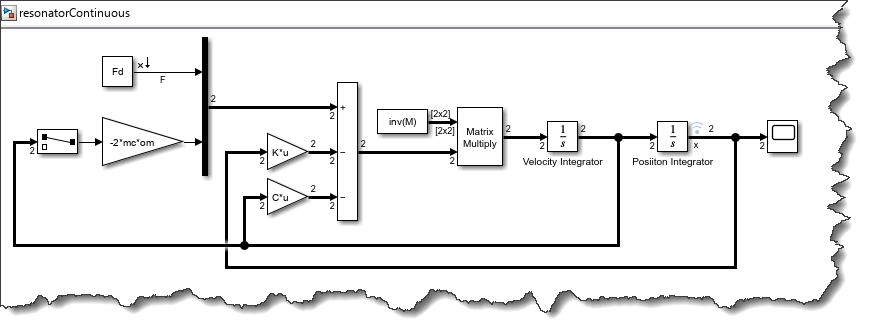

I picked coeffients such that the system has very little damping and is consequently close to instability. Here is what the simulation results look like:

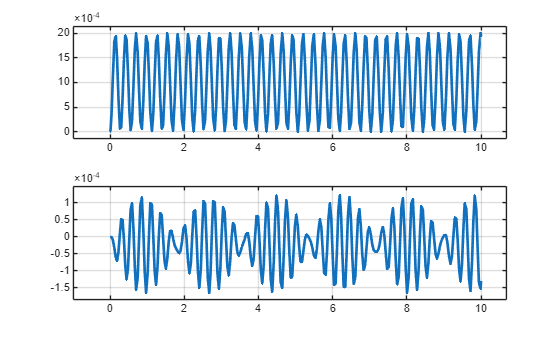

out = sim(mdl);
tiledlayout(2,1);
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,1))
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,2))

## Model Discretizer

If you use my favorite shortcut `Ctrl+.` or the open the Apps tab and search for something along the line of *discretization*, you will most likely find the [Model Discretizer](https://www.mathworks.com/help/simulink/ug/model-discretizer.html).

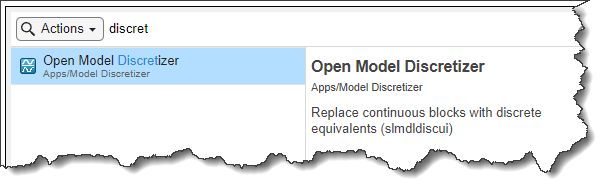

### Transform Method: Zero-Order Hold

As the description says, the Model Discretizer is a tool that helps replacing continuous blocks in a model with their discrete equivalent. It's easy to use: pick a trasnform method, a sample time (I chose 0.01sec), and click the "S->Z" button.

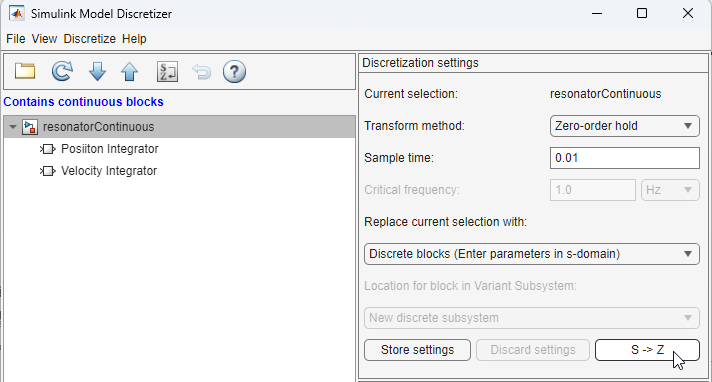

For this model, with the default transform method "`Zero-order hold`", it replaces the [Integrator](https://www.mathworks.com/help/simulink/slref/integrator.html) blocks with [Discrete-Time Integrator](https://www.mathworks.com/help/simulink/slref/discretetimeintegrator.html) blocks configured to use the Forward Euler integration method.

mdl = 'resonatorDiscrete';
open_system(mdl)

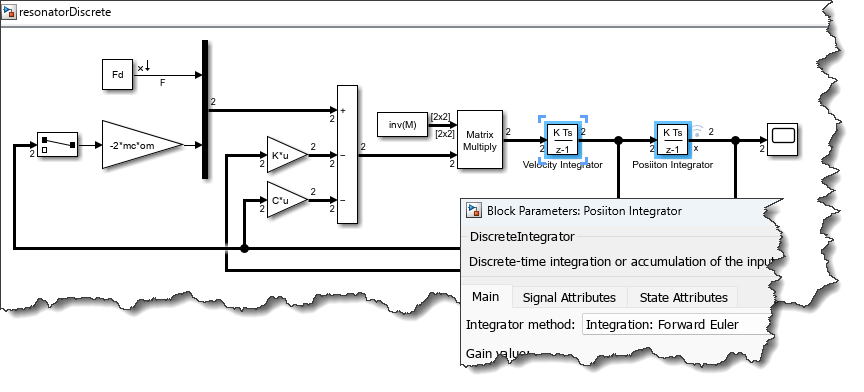

Unfortunately, when simulating the model, we quickly notice that the results are unstable and quickly diverge toward infinity.

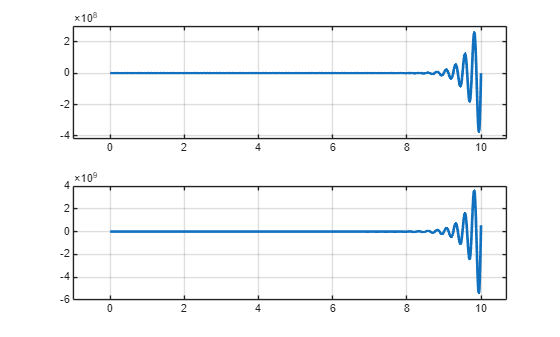

out = sim(mdl);
tiledlayout(2,1);
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,1))
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,2))

Since the Discrete-Time Integrator only executes at fixed major time steps, it cannot [uses results from minor time steps](https://www.mathworks.com/help/simulink/ug/types-of-sample-time.html#mw_ca6430dc-6eb1-499a-9353-36e277d6e706) to improve the accuracy of the result at the major time step like the contniuous Integrator block does.

### Transform Method: Tustin

I can try using a different method, for example "`Tustin`"

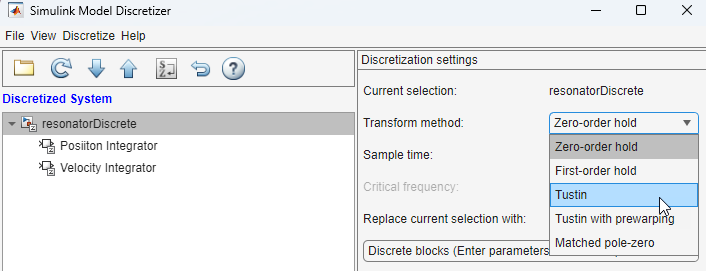

This time, the Discrete-Time Ingtegrator is configured to use the trapezoidal intgegration method:

mdl = 'resonatorDiscrete2';
open_system(mdl)

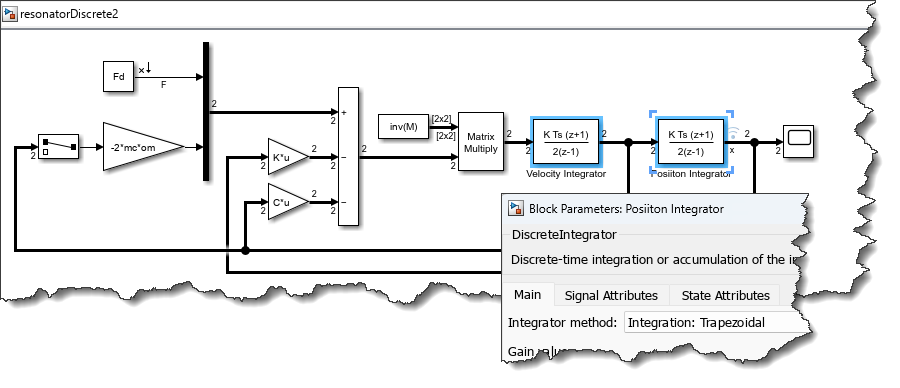

Simulating the model shows that the results are now what we expect, but we now get a warning about an algebraic loop:

out = sim(mdl);

Found algebraic loop that contains: 
resonatorDiscrete2/Product
resonatorDiscrete2/Velocity Integrator (discontinuity)
resonatorDiscrete2/Gain2
resonatorDiscrete2/Posiiton Integrator (discontinuity)
resonatorDiscrete2/Gain3
resonatorDiscrete2/Gain
resonatorDiscrete2/Sum (algebraic variable)


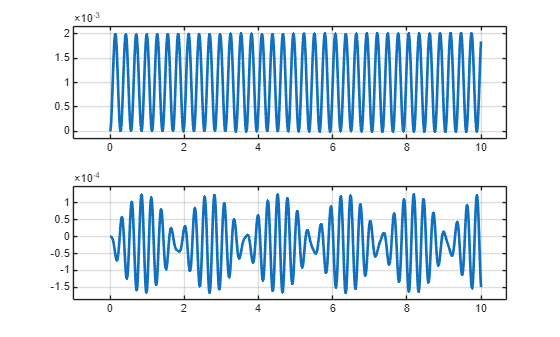

tiledlayout(2,1);
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,1))
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,2))

Since [Simulink Coder](https://www.mathworks.com/products/simulink-coder.html) cannot generate code for a model with algebraic loops, we need a different solution.

## The solution: [`c2d`](https://www.mathworks.com/help/control/ref/dynamicsystem.c2d.html)

Replacing continous Integrator blocks with Discrete-Time Integrator blocks can do the job in many cases. In this case, since our initial system is marginally stable, the delay introduced by the Forward Euler method of the Discrete-Time Integrator is too much and makes the system unstable.

Instead of converting only the Integrator blocks, what we can do is convert the full system. Let's see how to do that.

### Linearization

To use `c2d`, we need a continuous-time model, specified as a [dynamic system model](https://www.mathworks.com/help/control/ug/dynamic-system-models.html) such as [`tf`](https://www.mathworks.com/help/control/ref/tf.html), [`ss`](https://www.mathworks.com/help/control/ref/ss.html), or [`zpk`](https://www.mathworks.com/help/control/ref/zpk.html). In Simulink, a typical way to obtain that is through linearization. For that, open the [Linearization Manager](https://www.mathworks.com/help/slcontrol/ug/linearizationmanager-app.html), select the input and output signals and insset linearization analysis points:

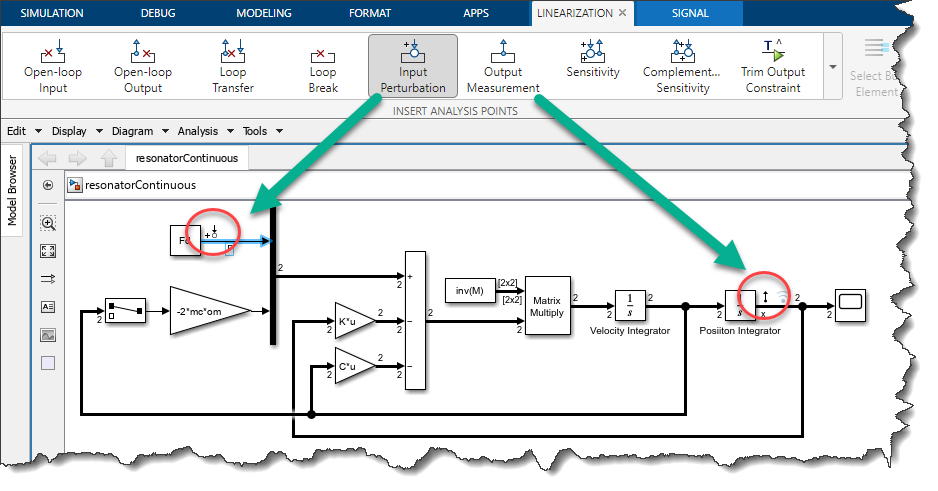

Once this is done, you can linearize the system:

mdl = 'resonatorContinuous';
io = getlinio(mdl);
sys = linearize(mdl,io)


sys =
 
  A = 
                 Position Int  Position Int  Velocity Int  Velocity Int
   Position Int             0             0             1             0
   Position Int             0             0             0             1
   Velocity Int          -500         -11.5       -0.0005             0
   Velocity Int           -14        -666.7      -0.06667    -0.0003333
 
  B = 
                   F
   Position Int    0
   Position Int    0
   Velocity Int  0.5
   Velocity Int    0
 
  C = 
         Position Int  Position Int  Velocity Int  Velocity Int
   x(1)             1             0             0             0
   x(2)             0             1             0             0
 
  D = 
         F
   x(1)  0
   x(2)  0
 
Continuous-time state-space model.


### Continuous to Discrete Conversion

Once we have the continuous model, it's as simple as passing it to `c2d`:

sysd = c2d(sys,0.01)


sysd =
 
  A = 
                 Position Int  Position Int  Velocity Int  Velocity Int
   Position Int        0.9751    -0.0005694      0.009917    -1.906e-06
   Position Int    -0.0006877        0.9669    -5.621e-06      0.009889
   Velocity Int        -4.958       -0.1128        0.9751    -0.0005694
   Velocity Int       -0.1356        -6.593     -0.001347        0.9668
 
  B = 
                          F
   Position Int    2.49e-05
   Position Int  -8.429e-09
   Velocity Int    0.004958
   Velocity Int   -2.81e-06
 
  C = 
         Position Int  Position Int  Velocity Int  Velocity Int
   x(1)             1             0             0             0
   x(2)             0             1             0             0
 
  D = 
         F
   x(1)  0
   x(2)  0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


### Back to Simulink

To bring this system back in Simulink, we can use either the [LTI System](https://www.mathworks.com/help/control/ref/ltisystem.html) block from [Simulink Control Design](https://www.mathworks.com/products/simcontrol.html), or the [Discrete State-Space](https://www.mathworks.com/help/simulink/slref/discretestatespace.html) block.

mdl = 'resonatorDiscreteLTI';
open_system(mdl)

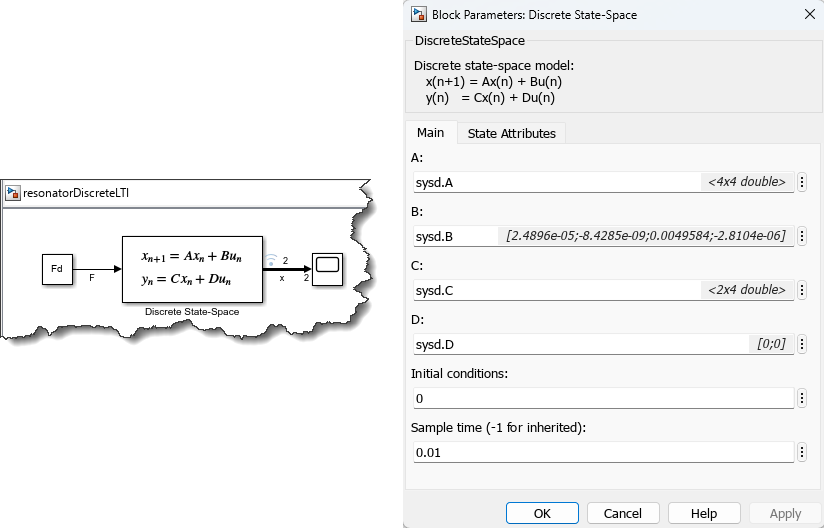

This time, the results match and there is no algebraic loop.

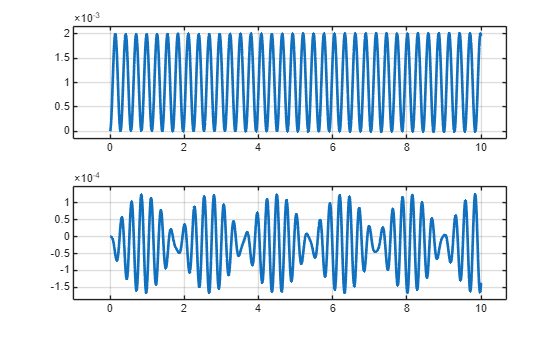

out = sim(mdl);
tiledlayout(2,1);
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,1))
nexttile;
plot(out.logsout.get('x').Values.Time,out.logsout.get('x').Values.Data(:,2))

## Now it's your turn

The system to be discretized in this example we simple, so the process was straightforward using default setting. For more complex systems, I recommend looking at [Continuous-Discrete Conversion Methods](https://www.mathworks.com/help/control/ug/continuous-discrete-conversion-methods.html).

Let us know what kind of challenges you are facing when converting continous simulation to fixed-step in the comments below.